n=-100:100;
x=cos(0.2*pi*n)+0.5*cos(0.6*pi*n)

x =     1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545


a=0.1;
k=50;
[xs,xsn]=sigshift(x,n,-k)

xs =     1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545    1.5000    0.6545   -0.0955    0.0955   -0.6545   -1.5000   -0.6545    0.0955   -0.0955    0.6545


xsn =    -50   -49   -48   -47   -46   -45   -44   -43   -42   -41   -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1


xs=a*xs;
[xs,xsn]=sigfold(xs,xsn)

xs =     0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655


xsn =   -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140  -139  -138  -137  -136  -135  -134  -133  -132  -131  -130  -129  -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118  -117  -116  -115  -114  -113  -112  -111  -110  -109  -108  -107  -106  -105  -104  -103  -102  -101


[y,yn]=sigadd(x,n,xs,xsn)

y =     0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655    0.1500    0.0655   -0.0095    0.0095   -0.0655   -0.1500   -0.0655    0.0095   -0.0095    0.0655


yn =   -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140  -139  -138  -137  -136  -135  -134  -133  -132  -131  -130  -129  -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118  -117  -116  -115  -114  -113  -112  -111  -110  -109  -108  -107  -106  -105  -104  -103  -102  -101


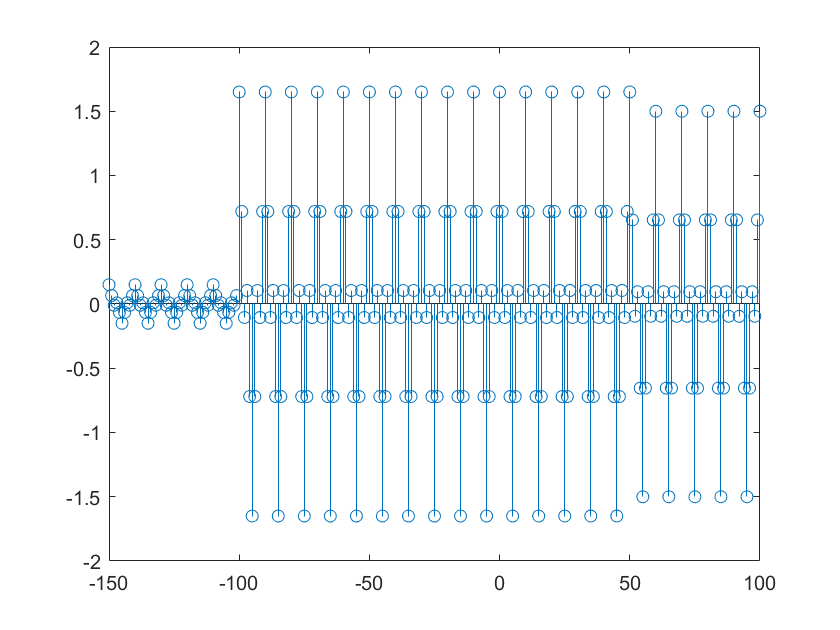

stem(yn,y)

[xc,xcn]=conv_i(xs,xsn,y,yn)

xc =     0.0225    0.0196    0.0014    0.0016   -0.0183   -0.0538   -0.0379   -0.0041    0.0011    0.0366    0.0850    0.0562    0.0068   -0.0037   -0.0549   -0.1163   -0.0745   -0.0094    0.0064    0.0732    0.1475    0.0928    0.0121   -0.0091   -0.0915   -0.1787   -0.1111   -0.0148    0.0117    0.1098    0.2100    0.1294    0.0174   -0.0144   -0.1281   -0.2412   -0.1477   -0.0201    0.0171    0.1464    0.2725    0.1660    0.0228   -0.0197   -0.1646   -0.3037   -0.1843   -0.0254    0.0224    0.1829


xcn =   -300  -299  -298  -297  -296  -295  -294  -293  -292  -291  -290  -289  -288  -287  -286  -285  -284  -283  -282  -281  -280  -279  -278  -277  -276  -275  -274  -273  -272  -271  -270  -269  -268  -267  -266  -265  -264  -263  -262  -261  -260  -259  -258  -257  -256  -255  -254  -253  -252  -251


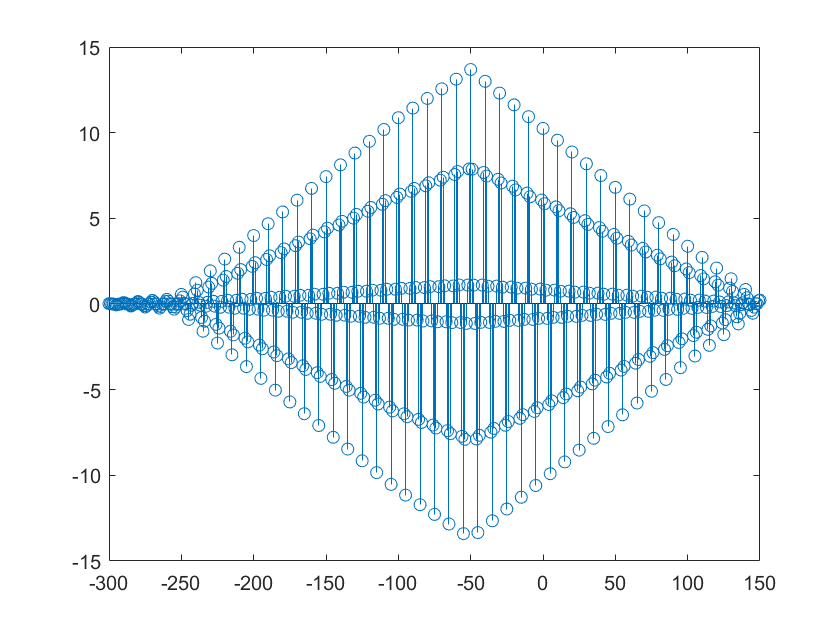

stem(xcn,xc)

legend('data point','mag value')